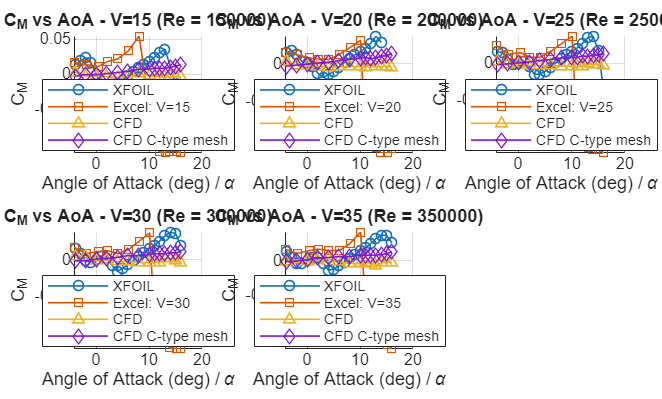

% compare_cm_all_graphs_only_option1.m

excelFile = "C:\Users\marke\Desktop\university\semester 8\Thesis\experiment\all series (Repaired).xlsx";
sheetNames = ["V=15", "V=20", "V=25", "V=30", "V=35"];

xfoilFiles = [ ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_150k_v15", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_200k_v20", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_250k_v25", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_300k_v30", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_350k_v35" ...
];

cfdCSV = "\\wsl.localhost\Ubuntu-22.04\home\mteggeri\OpenFOAM\mteggeri-13\run\naca0012_coefficients_summary.csv";
cfdCmeshFile = "\\wsl.localhost\Ubuntu-22.04\home\mteggeri\OpenFOAM\mteggeri-13\run\all_forceCoeffs_raw.dat";

lw = 0.8;
ms = 5;

n = numel(sheetNames);

% Option 1: known Reynolds numbers matching sheetNames order
Re_values = [150000, 200000, 250000, 300000, 350000];

% --- Read CFD CSV ---
Tc = readtable(cfdCSV, 'FileType','text');

% --- Read C-type mesh CFD data ---
optsC = delimitedTextImportOptions("NumVariables",6);
optsC.Delimiter = {' ','\t'};
optsC.ConsecutiveDelimitersRule = "join";
optsC.VariableNames = {'Velocity','AoA','Iter','CM','CD','CL'};
optsC.VariableTypes = repmat("double",1,6);

Tcmesh = readtable(cfdCmeshFile, optsC);

figure;
tiledlayout(2,3, 'TileSpacing','compact', 'Padding','compact');

for i = 1:n
    ax = nexttile;
    hold(ax,'on');

    label = sheetNames(i);
    Re = Re_values(i);  % use provided Re for the title

    % --- XFOIL ---
    try
        [alpha_x, CM_x] = parseXfoilCM(xfoilFiles(i));
        plot(ax, alpha_x, CM_x, '-o', ...
            'MarkerSize',ms, ...
            'LineWidth',lw, ...
            'DisplayName','XFOIL');
    catch ME
        warning('XFOIL read failed for %s: %s', xfoilFiles(i), ME.message);
    end

    % --- Excel ---
    try
        T2 = readtable(excelFile, 'Sheet', label);
        [idxA2, idxCM2] = findColumnsCM(T2);

        alpha_e = T2{:, idxA2};
        CM_e = T2{:, idxCM2};

        plot(ax, alpha_e, CM_e, '-s', ...
            'MarkerSize',ms, ...
            'LineWidth',lw, ...
            'DisplayName',['Excel: ' char(label)]);
    catch ME
        warning('Excel read failed for %s: %s', label, ME.message);
    end

    % --- CFD summary CSV ---
    try
        rows = matchCfdRows(Tc, label);

        if any(rows)
            Tc_sub = Tc(rows,:);
            [idxAc, idxCMc] = findColumnsCM(Tc_sub);

            alpha_c = double(Tc_sub{:, idxAc});
            CM_c = double(Tc_sub{:, idxCMc});

            [alpha_c, sidx] = sort(alpha_c);
            CM_c = CM_c(sidx);

            plot(ax, alpha_c, CM_c, '-^', ...
                'MarkerSize',ms, ...
                'LineWidth',lw, ...
                'DisplayName','CFD');
        else
            warning('No CFD rows matched for %s.', label);
        end
    catch ME
        warning('CFD processing failed for %s: %s', label, ME.message);
    end

    % --- CFD C-type mesh ---
    try
        vnum = sscanf(char(label),'V=%d');
        rowsC = Tcmesh.Velocity == vnum;

        if any(rowsC)
            Tcmesh_sub = Tcmesh(rowsC,:);

            alpha_ct = double(Tcmesh_sub.AoA);
            CM_ct = double(Tcmesh_sub.CM);

            [alpha_ct, sidx] = sort(alpha_ct);
            CM_ct = CM_ct(sidx);

            plot(ax, alpha_ct, CM_ct, '-d', ...
                'MarkerSize',ms, ...
                'LineWidth',lw, ...
                'DisplayName','CFD C-type mesh');
        else
            warning('No C-type CFD rows matched for %s.', label);
        end
    catch ME
        warning('C-type CFD failed for %s: %s', label, ME.message);
    end

    xlabel(ax, 'Angle of Attack (deg) / \alpha');
    ylabel(ax, 'C_M');
    title(ax, sprintf('C_M vs AoA - %s (Re = %d)', label, Re));
    legend(ax, 'Location','best');
    grid(ax,'on');
    hold(ax,'off');
end


%% Local helper functions

function [idxA, idxCM] = findColumnsCM(T)
    vars = lower(T.Properties.VariableNames);

    idxA = find(contains(vars, {'alpha','aoa','angle'}), 1);
    idxCM = find(contains(vars, {'cm','c_m','moment'}), 1);

    if isempty(idxA) || isempty(idxCM)
        numericCols = varfun(@isnumeric, T, 'OutputFormat','uniform');
        cols = find(numericCols);

        if numel(cols) >= 4
            if isempty(idxA), idxA = cols(1); end
            if isempty(idxCM), idxCM = cols(4); end
        elseif numel(cols) >= 2
            if isempty(idxA), idxA = cols(1); end
            if isempty(idxCM), idxCM = cols(end); end
        else
            error('Cannot detect AoA and CM columns.');
        end
    end
end

function rows = matchCfdRows(Tc, label)
    vars = lower(Tc.Properties.VariableNames);
    rows = false(height(Tc),1);

    numVelIdx = find(contains(vars,{'vel','velocity','uinf','speed','v'}), 1);

    if ~isempty(numVelIdx)
        varname = Tc.Properties.VariableNames{numVelIdx};
        col = Tc.(varname);
        nrows = height(Tc);
        vnum = nan(nrows,1);

        if isnumeric(col)
            vnum = double(col);
        elseif iscell(col)
            for k = 1:nrows
                vnum(k) = tryStr2num(col{k});
            end
        elseif ischar(col)
            s = cellstr(col);
            for k = 1:nrows
                vnum(k) = tryStr2num(s{k});
            end
        elseif isstring(col)
            for k = 1:nrows
                vnum(k) = tryStr2num(col(k));
            end
        end

        numLabel = sscanf(char(label),'V=%d');
        if isempty(numLabel)
            numLabel = sscanf(char(label),'V%d');
        end

        if ~isempty(numLabel)
            rows = vnum == numLabel;
        end
    end

    % fallback: text match in table cells
    if ~any(rows)
        cellMat = table2cell(Tc);
        [r,c] = size(cellMat);
        strMat = strings(r,c);

        for rr = 1:r
            for cc = 1:c
                val = cellMat{rr,cc};

                if isempty(val)
                    strMat(rr,cc) = "";
                elseif isnumeric(val)
                    strMat(rr,cc) = string(val);
                elseif isstring(val)
                    strMat(rr,cc) = val;
                elseif ischar(val)
                    strMat(rr,cc) = string(val);
                elseif iscell(val)
                    if isempty(val)
                        strMat(rr,cc) = "";
                    else
                        strMat(rr,cc) = string(val{1});
                    end
                else
                    strMat(rr,cc) = string(mat2str(val));
                end
            end
        end

        rowstr = join(strMat, ' ', 2);

        numOnly = char(extractAfter(char(label),'='));
        variants = unique([erase(char(label),'='), char(label), numOnly]);

        for k = 1:numel(variants)
            if ~isempty(variants{k})
                rows = rows | contains(rowstr, variants{k}, 'IgnoreCase', true);
            end
        end
    end
end

function n = tryStr2num(x)
    if isempty(x)
        n = NaN;
    elseif isnumeric(x)
        n = double(x);
    elseif ischar(x) || isstring(x)
        s = string(x);
        s = strrep(s, 'm/s', '');
        s = strrep(s, 'V=', '');
        s = strtrim(s);
        n = str2double(s);
    elseif iscell(x)
        if isempty(x)
            n = NaN;
        else
            n = tryStr2num(x{1});
        end
    else
        n = NaN;
    end
end

function [alpha, CM] = parseXfoilCM(fname)
    try
        T = readtable(fname, 'FileType','text');
        vars = lower(T.Properties.VariableNames);

        idxA = find(contains(vars,'alpha') | contains(vars,'aoa'),1);
        idxCM = find(contains(vars,'cm') | contains(vars,'c_m'),1);

        if isempty(idxA) || isempty(idxCM)
            data = readmatrix(fname, 'FileType','text');
            if size(data,2) < 4
                error('XFOIL_parse_fail');
            end
            alpha = data(:,1);
            CM = data(:,4);
        else
            alpha = T{:,idxA};
            CM = T{:,idxCM};
        end
    catch
        data = readmatrix(fname, 'FileType','text');
        if size(data,2) < 4
            error('Cannot parse CM from XFOIL file: %s', fname);
        end
        alpha = data(:,1);
        CM = data(:,4);
    end

    alpha = alpha(:);
    CM = CM(:);
end
